% Luke McCubbin 
%Sinewave test 
clear all;


% Parameters
npoints = 90000;  % Number of points
chip = 100e6;    % 100 MHz signal bandwidth
Amax = 1;        % Maximum amplitude (before normalization)
Fs = chip * 10;  % Sampling frequency
phase_shift = 0;  % Phase shift in radians (for example, pi/4)

% Time vector
t = (0:npoints-1)/Fs;

% Frequency of the sine wave
f = chip;

% Generate complex sine wave with phase shift
complex_sine_wave = 0.31623 * exp(1j * (2 * pi * f * t + phase_shift));

% Get the unwrapped phase
raw_phase        = angle(complex_sine_wave);
unwrapped_phase  = unwrap(raw_phase);

% Fit unwrapped_phase = 2*pi*f * t + phi
p           = polyfit(t, unwrapped_phase, 1);
slope       = p(1);    % ~ 2*pi*f
intercept   = p(2);    % ~ phase_shift

% fprintf("True Phase Shift:      %f\n", phase_shift);
% fprintf("Estimated Phase Shift: %f\n", intercept);
% fprintf("Estimated Frequency:   %f Hz\n", slope / (2*pi));


% Normalize the real and imaginary parts to be between 0 and 1
real_part_normalized = real(complex_sine_wave);
imag_part_normalized = imag(complex_sine_wave);




% Loop over Pinc values from -15 to 15
power_dBm_array = zeros(1, 41); % Preallocate for -15 to 15 (31 values)
phase_dBm_array = zeros(1, 41); % Preallocate for -15 to 15 (31 values)

power_dBm_distorted_array = zeros(1, 41); % Preallocate for -15 to 15 (31 values)
phase_dBm_distorted_array = zeros(1, 41); % Preallocate for -15 to 15 (31 values)

pin_power = zeros(1, 41);

for Pinc_index = 1:41
    Pinc = 4.5 + Pinc_index/2; 

    complex_sine_wave = 10^(Pinc/20) * 0.31623 * exp(1j * (2 * pi * f * t + phase_shift));

    % Calculate power_dBm_distorted
    power_avg = trapz(t, abs(complex_sine_wave).^2) / ((t(end) - t(1)) * 100);
    power_dBm = 10 * log10(power_avg / 1e-3);
    fprintf('Sine output Average Power for Pinc = %d dBm: %f dBm\n', Pinc, power_dBm);

    % Store the result in the array
    power_dBm_array(Pinc_index) = power_dBm;

    
    % Create a table for the real part
    % xI_table = array2table(complex_sine_wave', 'VariableNames', {'xI'});
    % 
    % filename = sprintf("C:\\Users\\Luke McCubbin\\Box\\NN PA DPD\\DPD_test_1\\V2\\sinewaves\\sine_test_%d.csv", Pinc_index);
    % 
    % % Write the table to a separate CSV file
    % writetable(xI_table, filename);

    pin_power(Pinc_index) = Pinc;

    %Results processing
    filename = sprintf('C:\\Users\\Luke McCubbin\\Box\\NN PA DPD\\DPD_test_1\\V3_0306\\sineresults10db\\sine_result_%d.mat', Pinc_index);
    load(filename)

    % Calculate power_dBm_distorted
    power_avg_distorted = trapz(t, abs(yout_predict).^2) / ((t(end) - t(1)) * 100);
    power_dBm_distorted = 10 * log10(power_avg_distorted / 1e-3);
    fprintf('NN output Average Power for Pinc = %d dBm: %f dBm\n', Pinc, power_dBm_distorted);

    % Store the result in the array
    power_dBm_distorted_array(Pinc_index) = power_dBm_distorted;

    % Get the unwrapped phase
    raw_phase        = angle(yout_predict);
    unwrapped_phase  = unwrap(raw_phase);

    % Fit unwrapped_phase = 2*pi*f * t + phi
    p           = polyfit(t, unwrapped_phase, 1);
    slope       = p(1);    % ~ 2*pi*f
    intercept   = p(2);    % ~ phase_shift

    phase_dBm_distorted_array(Pinc_index) = rad2deg(intercept);

    %fprintf("Estimated Phase Shift (radians): %f\n", intercept);
    %fprintf("Estimated Frequency:   %f Hz\n", slope / (2*pi));

   %  %Phase calculations:
   %  phase_xI = angle(complex_sine_wave);
   %  phase_yout = angle(yout_predict);
   %  % Phase difference
   %  %phase_diff = phase_yout + phase_xI;
   %  phase_diff = phase_yout;
   % 
   %  phase_diff_unwrapped = unwrap(phase_diff);
   %  %phase_diff_unwrapped = phase_diff;
   % 
   %  % Calculate the mean phase shift
   %  phase_shift = mean(phase_diff_unwrapped);
   % 
   %  phase_shift_deg = rad2deg(phase_shift)
   % 
   %  % Store the result in the array
   % phase_dBm_distorted_array(Pinc_index) = rad2deg(intercept);

    % % Compute the phase of each signal
    % phase_xI = angle(complex_sine_wave); % Phase of the reference signal
    % phase_yout = angle(yout_predict);   % Phase of the predicted signal
    % 
    % % Unwrap the phases
    % phase_xI_unwrapped = unwrap(phase_xI);
    % phase_yout_unwrapped = unwrap(phase_yout);
    % 
    % phase_xI_mean = mean(phase_xI_unwrapped)
    % phase_yout_mean = mean(phase_yout_unwrapped)
    % 
    % % Compute the phase difference
    % phase_diff_unwrapped = phase_xI_mean + phase_yout_mean;
    % 
    % % Calculate the mean phase shift
    % %phase_shift = mean(phase_diff_unwrapped);
    % phase_shift = phase_diff_unwrapped;
    % 
    % 
    % % Convert the mean phase shift to degrees
    % phase_shift_deg = rad2deg(phase_shift);
    % 
    % % Store the result in the array
    % phase_dBm_distorted_array(Pinc_index) = phase_shift_deg;




   %  %Create a table for the real part
   %  xI_table = array2table(complex_sine_wave', 'VariableNames', {'xI'});
   % 
   %  filename = sprintf("C:\\Users\\Luke McCubbin\\Box\\NN PA DPD\\DPD_test_1\\V2\\sinewaves\\sine_test_%d.csv", Pinc_index);
   % 
   % % Write the table to a separate CSV file
   %  writetable(xI_table, filename);

end

Sine output Average Power for Pinc = 5 dBm: 5.000061 dBm


NN output Average Power for Pinc = 5 dBm: 19.537143 dBm


Sine output Average Power for Pinc = 5.500000e+00 dBm: 5.500061 dBm


NN output Average Power for Pinc = 5.500000e+00 dBm: 20.030542 dBm


Sine output Average Power for Pinc = 6 dBm: 6.000061 dBm


NN output Average Power for Pinc = 6 dBm: 20.519911 dBm


Sine output Average Power for Pinc = 6.500000e+00 dBm: 6.500061 dBm


NN output Average Power for Pinc = 6.500000e+00 dBm: 21.005670 dBm


Sine output Average Power for Pinc = 7 dBm: 7.000061 dBm


NN output Average Power for Pinc = 7 dBm: 21.489527 dBm


Sine output Average Power for Pinc = 7.500000e+00 dBm: 7.500061 dBm


NN output Average Power for Pinc = 7.500000e+00 dBm: 21.968365 dBm


Sine output Average Power for Pinc = 8 dBm: 8.000061 dBm


NN output Average Power for Pinc = 8 dBm: 22.440908 dBm


Sine output Average Power for Pinc = 8.500000e+00 dBm: 8.500061 dBm


NN output Average Power for Pinc = 8.500000e+00 dBm: 22.898348 dBm


Sine output Average Power for Pinc = 9 dBm: 9.000061 dBm


NN output Average Power for Pinc = 9 dBm: 23.348051 dBm


Sine output Average Power for Pinc = 9.500000e+00 dBm: 9.500061 dBm


NN output Average Power for Pinc = 9.500000e+00 dBm: 23.791247 dBm


Sine output Average Power for Pinc = 10 dBm: 10.000061 dBm


NN output Average Power for Pinc = 10 dBm: 24.227003 dBm


Sine output Average Power for Pinc = 1.050000e+01 dBm: 10.500061 dBm


NN output Average Power for Pinc = 1.050000e+01 dBm: 24.653133 dBm


Sine output Average Power for Pinc = 11 dBm: 11.000061 dBm


NN output Average Power for Pinc = 11 dBm: 25.078243 dBm


Sine output Average Power for Pinc = 1.150000e+01 dBm: 11.500061 dBm


NN output Average Power for Pinc = 1.150000e+01 dBm: 25.503067 dBm


Sine output Average Power for Pinc = 12 dBm: 12.000061 dBm


NN output Average Power for Pinc = 12 dBm: 25.927845 dBm


Sine output Average Power for Pinc = 1.250000e+01 dBm: 12.500061 dBm


NN output Average Power for Pinc = 1.250000e+01 dBm: 26.348818 dBm


Sine output Average Power for Pinc = 13 dBm: 13.000061 dBm


NN output Average Power for Pinc = 13 dBm: 26.766840 dBm


Sine output Average Power for Pinc = 1.350000e+01 dBm: 13.500061 dBm


NN output Average Power for Pinc = 1.350000e+01 dBm: 27.180562 dBm


Sine output Average Power for Pinc = 14 dBm: 14.000061 dBm


NN output Average Power for Pinc = 14 dBm: 27.591007 dBm


Sine output Average Power for Pinc = 1.450000e+01 dBm: 14.500061 dBm


NN output Average Power for Pinc = 1.450000e+01 dBm: 27.998208 dBm


Sine output Average Power for Pinc = 15 dBm: 15.000061 dBm


NN output Average Power for Pinc = 15 dBm: 28.403064 dBm


Sine output Average Power for Pinc = 1.550000e+01 dBm: 15.500061 dBm


NN output Average Power for Pinc = 1.550000e+01 dBm: 28.800551 dBm


Sine output Average Power for Pinc = 16 dBm: 16.000061 dBm


NN output Average Power for Pinc = 16 dBm: 29.178706 dBm


Sine output Average Power for Pinc = 1.650000e+01 dBm: 16.500061 dBm


NN output Average Power for Pinc = 1.650000e+01 dBm: 29.540280 dBm


Sine output Average Power for Pinc = 17 dBm: 17.000061 dBm


NN output Average Power for Pinc = 17 dBm: 29.895925 dBm


Sine output Average Power for Pinc = 1.750000e+01 dBm: 17.500061 dBm


NN output Average Power for Pinc = 1.750000e+01 dBm: 30.254150 dBm


Sine output Average Power for Pinc = 18 dBm: 18.000061 dBm


NN output Average Power for Pinc = 18 dBm: 30.613527 dBm


Sine output Average Power for Pinc = 1.850000e+01 dBm: 18.500061 dBm


NN output Average Power for Pinc = 1.850000e+01 dBm: 30.978959 dBm


Sine output Average Power for Pinc = 19 dBm: 19.000061 dBm


NN output Average Power for Pinc = 19 dBm: 31.348054 dBm


Sine output Average Power for Pinc = 1.950000e+01 dBm: 19.500061 dBm


NN output Average Power for Pinc = 1.950000e+01 dBm: 31.721335 dBm


Sine output Average Power for Pinc = 20 dBm: 20.000061 dBm


NN output Average Power for Pinc = 20 dBm: 32.098486 dBm


Sine output Average Power for Pinc = 2.050000e+01 dBm: 20.500061 dBm


NN output Average Power for Pinc = 2.050000e+01 dBm: 32.479106 dBm


Sine output Average Power for Pinc = 21 dBm: 21.000061 dBm


NN output Average Power for Pinc = 21 dBm: 32.863091 dBm


Sine output Average Power for Pinc = 2.150000e+01 dBm: 21.500061 dBm


NN output Average Power for Pinc = 2.150000e+01 dBm: 33.252158 dBm


Sine output Average Power for Pinc = 22 dBm: 22.000061 dBm


NN output Average Power for Pinc = 22 dBm: 33.646510 dBm


Sine output Average Power for Pinc = 2.250000e+01 dBm: 22.500061 dBm


NN output Average Power for Pinc = 2.250000e+01 dBm: 34.045699 dBm


Sine output Average Power for Pinc = 23 dBm: 23.000061 dBm


NN output Average Power for Pinc = 23 dBm: 34.449391 dBm


Sine output Average Power for Pinc = 2.350000e+01 dBm: 23.500061 dBm


NN output Average Power for Pinc = 2.350000e+01 dBm: 34.856760 dBm


Sine output Average Power for Pinc = 24 dBm: 24.000061 dBm


NN output Average Power for Pinc = 24 dBm: 35.267510 dBm


Sine output Average Power for Pinc = 2.450000e+01 dBm: 24.500061 dBm


NN output Average Power for Pinc = 2.450000e+01 dBm: 35.682170 dBm


Sine output Average Power for Pinc = 25 dBm: 25.000061 dBm


NN output Average Power for Pinc = 25 dBm: 36.100927 dBm


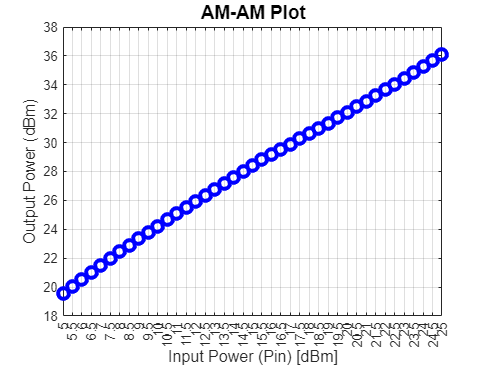

% Plotting the AM-PM plot
figure(5);
plot(pin_power, power_dBm_distorted_array, 'bo','LineWidth', 3, 'MarkerSize', 8);  % Plot with markers
grid on;  % Add grid for better visualization
% Labeling the plot
xticks(5:0.5:25);  % Set x-axis ticks to discrete values from -15 to 15
xlabel('Input Power (Pin) [dBm]', 'FontSize', 12);  % X-axis label
ylabel('Output Power (dBm)', 'FontSize', 12);  % Y-axis label
title('AM-AM Plot', 'FontSize', 14);  % Title of the plot

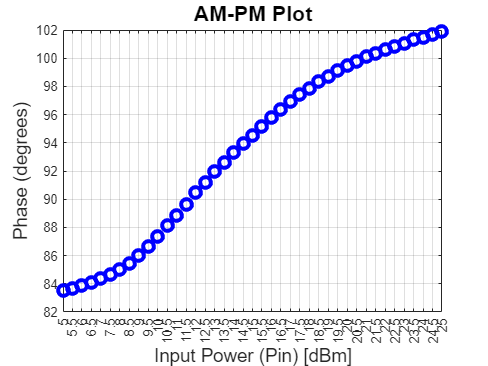


% Plotting the AM-PM plot
figure(6);
plot(pin_power, phase_dBm_distorted_array,'bo', 'LineWidth', 3, 'MarkerSize', 8);  % Plot with markers
grid on;  % Add grid for better visualization
% Labeling the plot
xticks(5:0.5:25);  % Set x-axis ticks to discrete values from -15 to 15
xlabel('Input Power (Pin) [dBm]', 'FontSize', 14);  % X-axis label
ylabel('Phase (degrees)', 'FontSize', 14);  % Y-axis label
title('AM-PM Plot', 'FontSize', 16);  % Title of the plot